% %%  B21 解析法绘制点电荷对的电力线
% x=(-1:.125:1);
% y=(-1:.125:1);
% [X,Y] = meshgrid(x,y);            %设置网格区域
% EX=(X-sqrt(2))./(Y.^2+(X-sqrt(2)).^2).^(3/2)-(X+sqrt(2))./(Y.^2+(X+sqrt(2)).^2).^(3/2);   
% %电场强度x分量；
% EY=(Y)./(Y.^2+(X-sqrt(2)).^2).^(3/2)-(Y)./(Y.^2+(X+sqrt(2)).^2).^(3/2);   %电场强度y分量
% quiver(X,Y,EX,EY);               %绘制电力线
% axis([-1 1 -1 1]);                  %设置显示范围 


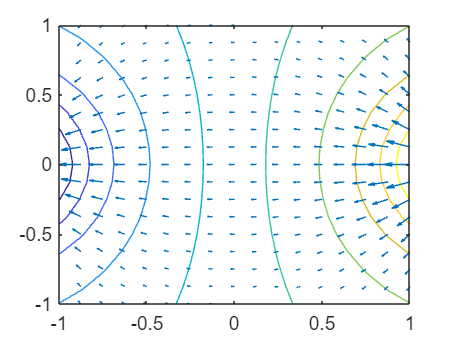

%%  B22 数值方法绘制点电荷对的电力线
x=(-1:.125:1);
y=(-1:.125:1);
[X,Y] = meshgrid(x,y);	%创建网格
Phi =(1./sqrt(Y.^2+(X-sqrt(2)).^2)-1./sqrt(Y.^2+(X+sqrt(2)).^2));    %电势函数的表达式
[DX,DY] = gradient(-Phi); 	%数值计算电势的负梯度，即电场强度，并存储在DX、DY中
contour(X,Y,Phi,10);     	%绘制等势线，一共10条
hold on;               	%告诉MATLAB使用叠加绘图模式，不要覆盖前面的图像
quiver(X,Y,DX,DY);     	%绘制电力线，并与前面的等势线叠加在一幅图中
axis([-1 1 -1 1]);       	%设置显示范围x、y都是从－1到1

% 

% %% B32 两个不等量异号电荷对应的电力线分布
% x=-4:0.02:4;y=x;                     	%生成一系列坐标x,y
% [X,Y]=meshgrid(x,y);                 	%生成网格数据
% R1=sqrt((X+1).^2+Y.^2);              	%场点距离左侧电荷的距离
% R2=sqrt((X-1).^2+Y.^2);               	%场点距离右侧电荷的距离
% phi=1./R1-2./R2;                     	%计算电势（Q*=q2/q1=-2），忽略系数
% [Ex,Ey]=gradient(-phi);                	%取梯度计算电场
% hold on;                            	%叠加绘图模式
% r0=0.1;                             	%电场线起点所在圆半径
% th=20:20:360-20;                     	%以20度为间隔，均分圆周
% th=th*pi/180;                        	%化角度为弧度
% xl=r0*cos(th)-1;                      	%左侧电荷起点横坐标
% yl=r0*sin(th);                        	%左侧电荷起点纵坐标
% h=streamline(X,Y,Ex,Ey,xl,yl);          	%绘制左侧电荷对应的流线，即为电场线
% xr=-xl;                            	%右侧电荷对应的起始点横坐标          
% yr=yl;                             	%右侧电荷对应的起始点纵坐标          
% h=streamline(X,Y,-Ex,-Ey,xr,yr);       	%绘制右侧电荷对应的流线
% axis image;                        	%等比例绘制图像


x=(-1:.125:1);
y=(-1:.125:1);
[X,Y] = meshgrid(x,y);	%创建网格
